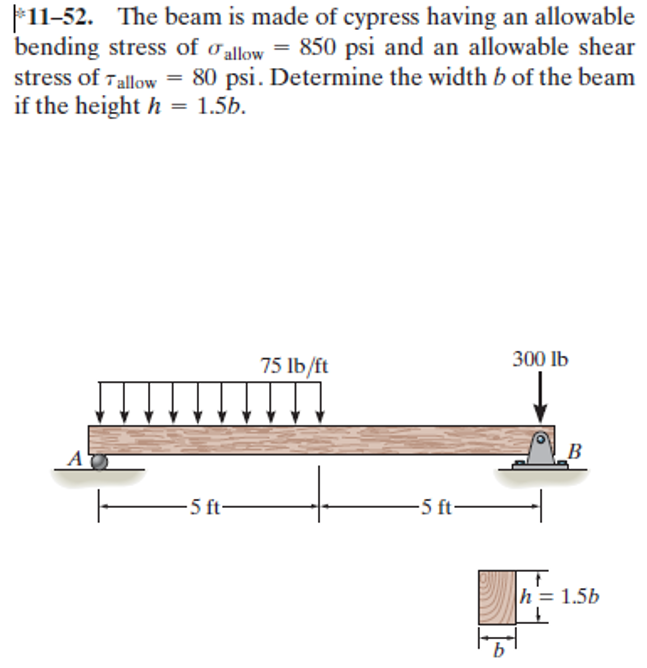

# assumptions

old_assum = assumptions;
clearassum;

# allowable stresses

u = symunit;
sigma_allow = 850*u.psi;
tau_allow = 80*u.psi;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 10*u.ft);
b = b.add('applied', 'force', -300*u.lbf, 10*u.ft);
b = b.add('distributed', 'force', -75*u.lbf/u.ft, [0 5]*u.ft);
b.L = 10*u.ft;

# section properties

B = sym('B', 'positive');
H(B) = 1.5*B;
b.I = B*H^3/12;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{50\,x\,\left(2\,x^{3}-30\,x^{2}\,\mathrm{ft}+1125\,{\mathrm{ft}}^{3}\right)}{9\,B^{4}\,\text{E}}\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -\frac{250\,\left(x-10\,\mathrm{ft}\right)\,\left(2\,x^{2}-40\,x\,\mathrm{ft}+25\,{\mathrm{ft}}^{2}\right)}{9\,B^{4}\,\text{E}}\,\mathrm{lbf} & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{50\,\left(8\,x^{3}-90\,x^{2}\,\mathrm{ft}+1125\,{\mathrm{ft}}^{3}\right)}{9\,B^{4}\,\text{E}}\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -\frac{250\,\left(6\,x^{2}-120\,x\,\mathrm{ft}+425\,{\mathrm{ft}}^{2}\right)}{9\,B^{4}\,\text{E}}\,\mathrm{lbf} & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{75\,x\,\left(2\,x-15\,\mathrm{ft}\right)}{4}\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -\frac{375\,\left(x-10\,\mathrm{ft}\right)}{4}\,\mathrm{lbf} & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{75\,\left(4\,x-15\,\mathrm{ft}\right)}{4}\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -\frac{375}{4}\,\mathrm{lbf} & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -75\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ 0 & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

addvar(y);

# reactions

Ra = vpa(r.Ra) %#ok

$$Ra = 281.25\,\mathrm{lbf}$$

Rb = vpa(r.Rb) %#ok

$$Rb = 393.75\,\mathrm{lbf}$$

clear Ra Rb;

# shear and moment diagram

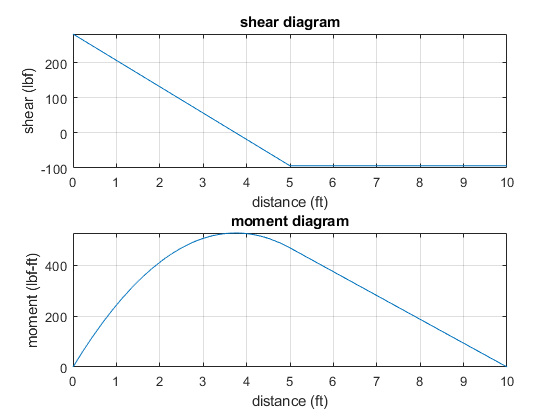

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});

# maximum bending stress

x_max = solve(v == 0);
M_max = m(x_max);
C = H/2;
sigma_max = rewrite(M_max*C/b.I, [u.psi u.in]);
B_min.bending = simplify(solve(sigma_allow == sigma_max));
B_min_bending = vpa(B_min.bending, 3) %#ok

$$B\_min\_bending = 2.71\,\mathrm{in}$$

clear B_min_bending;

# maximum shear stress

V_max = v(0);
A = B*H;
tau_max = rewrite(1.5*V_max/A, [u.psi u.in]);
B_min.shear = simplify(solve(tau_allow == tau_max));
B_min_shear = vpa(B_min.shear, 3) %#ok

$$B\_min\_shear = 1.88\,\mathrm{in}$$

clear B_min_shear;

# minimum width b

B_min_vals = [B_min.bending; B_min.shear];
in_range = isAlways(sigma_max(B_min_vals) <= sigma_allow & tau_max(B_min_vals) <= tau_allow);
B_min.design = B_min_vals(in_range);
B_min_design = vpa(B_min.design, 3) %#ok

$$B\_min\_design = 2.71\,\mathrm{in}$$

setassum(old_assum, 'clear');
clear B_min_design old_assum;